Punto 2a

Nx = 1024;
Ny = 1024;

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Cambio
dx =0.1*um;
dy =0.1*um;

waveLength = 650*nm;

m = 1;
L = 10*dx;

n = 1;
z = n*((L^2)/waveLength);

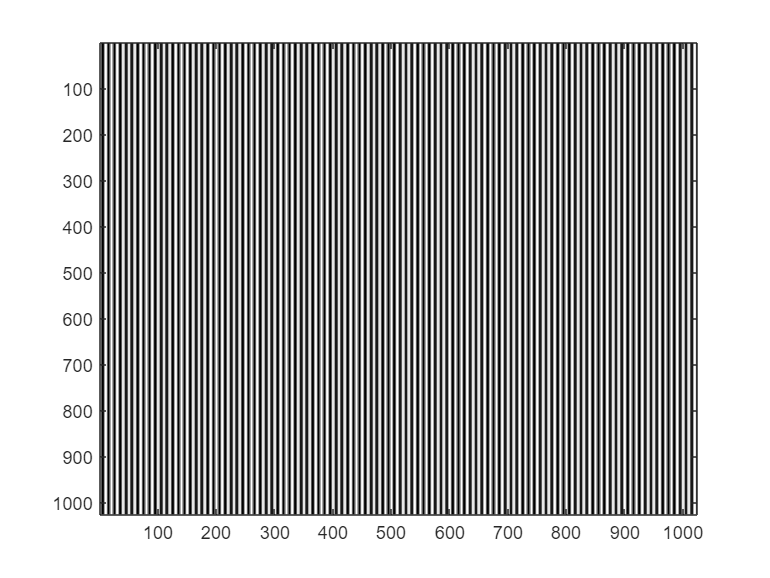

transmitancia = rejillaPunto2(Nx,Ny,dx,dy,m,L);
imagesc(transmitancia)
colormap('gray')

tic
transmitanciaProp = espectroAngular(transmitancia,dx,dy,z,waveLength,dft=false);
toc

Elapsed time is 0.078015 seconds.


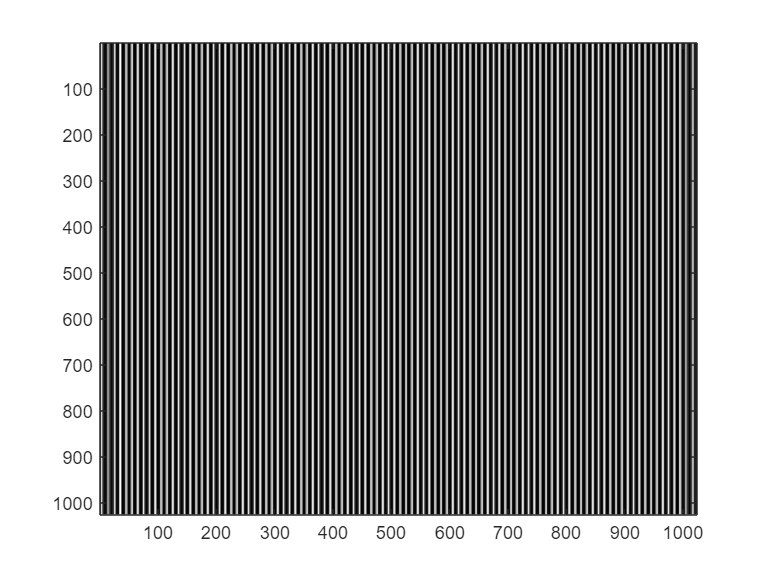

imagesc(abs(transmitanciaProp).^2)